SIVACHANDRA K B

CB.SC.P2DSC24018

## **Chronic Kidney Disease Prediction using SingularValue Decomposition (SVD)**

This study aims to predict Chronic Kidney Disease (CKD) using a dimensionality reduction approach based on Singular Value Decomposition (SVD), followed by a logistic regression classifier. The methodology involves data preprocessing, dimensionality reduction with SVD, model training, and evaluation.

The dataset used in this study consists of various features related to patient health, such as age, blood pressure, and blood glucose levels. Initial preprocessing steps include:

1.** Loading and Checking Data**: The dataset was loaded, and columns were inspected to identify target and feature columns.

2. **Binary Encoding of Target Variable**: The target variable, ”class,” was converted to a binary format with 1 for ”ckd” (indicating CKD presence) and 0 for ”notckd” (indicating absence).

3. **Handling Missing Values:** Missing values in the numerical feature columns were replaced with the column mean, ensuring no loss of data and enabling a consistent data matrix for subsequent analysis

% Medical Analysis on Chronic Kidney Disease

% Load the dataset
data = readtable("C:\Users\hp\OneDrive\Desktop\SVD projects\siva\kidney_disease.csv");

% Check column names to confirm the target column name
disp(data.Properties.VariableNames);

    {'id'}    {'age'}    {'bp'}    {'sg'}    {'al'}    {'su'}    {'rbc'}    {'pc'}    {'pcc'}    {'ba'}    {'bgr'}    {'bu'}    {'sc'}    {'sod'}    {'pot'}    {'hemo'}    {'pcv'}    {'wc'}    {'rc'}    {'htn'}    {'dm'}    {'cad'}    {'appet'}    {'pe'}    {'ane'}    {'classification'}




% Convert 'class' (or target) column to binary (1 for 'ckd', 0 for 'notckd')
if iscell(data.classification)
    data.class = strcmp(data.classification, 'ckd');  % Returns logical array (1 for 'ckd', 0 for 'notckd')
end

% Define numerical columns for SVD (update as needed)
numericalColumns = {'age', 'bp', 'bgr', 'bu', 'sc', 'sod', 'pot', 'hemo', 'pcv', 'wc', 'rc'};
numericalData = data(:, numericalColumns);

% Convert numerical data to array and handle missing values
X = table2array(numericalData);
for i = 1:size(X, 2)
    col = X(:, i);
    missingIdx = isnan(col);
    col(missingIdx) = mean(col(~missingIdx), 'omitnan');
    X(:, i) = col;
end
y = data.class;  % Updated binary target column

% Perform SVD for dimensionality reduction
[U, S, V] = svd(X, 'econ');

% Display U, S, and V matrices
disp("U:");

U:


disp(U);

   -0.0444    0.0005    0.0014   -0.0373   -0.0042    0.0164    0.0270   -0.0189   -0.0116    0.0501    0.0010
   -0.0342   -0.0288    0.0261   -0.0366   -0.1243   -0.0583   -0.0496    0.0617    0.0040   -0.0378   -0.0078
   -0.0428   -0.1658    0.0833    0.0483   -0.0011   -0.0094   -0.0387    0.0020    0.0076   -0.0155   -0.0510
   -0.0382   -0.0091   -0.0159   -0.0108    0.0167    0.0218    0.0170   -0.0073    0.0256    0.0369    0.0046
   -0.0416    0.0033    0.0023   -0.0490    0.0133    0.0279   -0.0419    0.0242   -0.0081   -0.0036   -0.0097
   -0.0444    0.0245   -0.0084   -0.0631    0.0402    0.0520   -0.0224    0.0023    0.0161   -0.0256    0.0326
   -0.0479    0.0217   -0.0119    0.0060    0.0842    0.0245    0.1194    0.1899    0.0145    0.0237   -0.0396
   -0.0393   -0.1612    0.0997    0.0326   -0.1129   -0.0062    0.0344   -0.0125    0.0010   -0.0422   -0.0016
   -0.0547    0.0102   -0.0073   -0.0047    0.0042    0.0880   -0.0258   -0.0225   -0.0069   -0.0034    0.0277
 

disp("V:");

V:


disp(V);

   -0.0057   -0.1292   -0.1201   -0.1835    0.9567   -0.1386    0.0129   -0.0238   -0.0053   -0.0048   -0.0019
   -0.0084   -0.1707   -0.1767   -0.3495    0.0142    0.8960    0.0789   -0.0894   -0.0119    0.0022    0.0017
   -0.0165   -0.9146    0.3330    0.2236   -0.0423   -0.0220    0.0096   -0.0032    0.0011    0.0013    0.0001
   -0.0063   -0.2242   -0.8872    0.3778   -0.0828   -0.0790    0.0300   -0.0750    0.0145    0.0074   -0.0010
   -0.0003   -0.0145   -0.0566    0.0361    0.0269    0.0663    0.3206    0.9378    0.0863   -0.0207    0.0094
   -0.0150   -0.2500   -0.2273   -0.7462   -0.2444   -0.3312   -0.3618    0.1602    0.0486   -0.0169    0.0147
   -0.0005   -0.0135   -0.0252   -0.0152   -0.0135   -0.0160   -0.0099    0.0943   -0.9937   -0.0435   -0.0128
   -0.0014   -0.0186   -0.0075   -0.0931   -0.0306   -0.0684    0.2262   -0.0444   -0.0463    0.9589    0.1024
   -0.0042   -0.0603   -0.0280   -0.2889   -0.1192   -0.2277    0.8396   -0.2642   -0.0111   -0.2643    0.0376
 


% Choose the number of components to keep
k = 5; % Number of components to keep
X_reduced = U(:, 1:k) * S(1:k, 1:k);

% Display the singular values
singular_values = diag(S);
disp('Singular values:');

Singular values:


disp(singular_values);

   1.0e+05 *

    1.7557
    0.0173
    0.0101
    0.0085
    0.0032
    0.0026
    0.0013
    0.0008
    0.0005
    0.0003
    0.0001



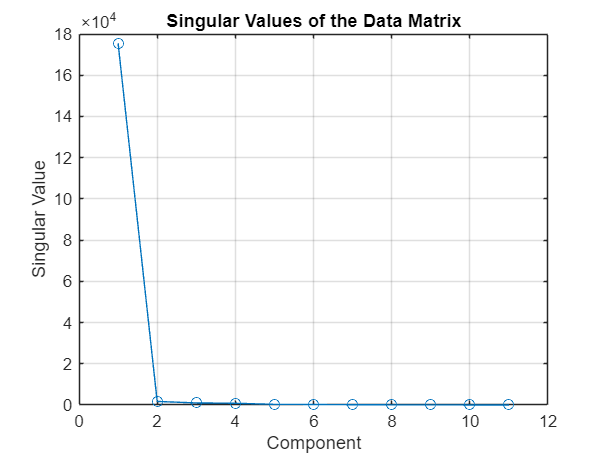


% Plot singular values to observe the variance captured by each component
figure;
plot(singular_values, 'o-');
title('Singular Values of the Data Matrix');
xlabel('Component');
ylabel('Singular Value');
grid on;


% Train-test split (70% train, 30% test)
cv = cvpartition(size(X_reduced, 1), 'HoldOut', 0.3);
X_train = X_reduced(training(cv), :);
y_train = y(training(cv));
X_test = X_reduced(test(cv), :);
y_test = y(test(cv));

% Train logistic regression model
mdl = fitclinear(X_train, y_train, 'Learner', 'logistic');

% Predict on test data
y_pred = predict(mdl, X_test);

% Display reduced dimensionality data
disp(['Reduced dimension representation with ', num2str(k), ' components:']);

Reduced dimension representation with 5 components:


disp(X_reduced);

   1.0e+04 *

   -0.7803    0.0001    0.0001   -0.0032   -0.0001
   -0.6003   -0.0050    0.0026   -0.0031   -0.0040
   -0.7508   -0.0287    0.0084    0.0041   -0.0000
   -0.6703   -0.0016   -0.0016   -0.0009    0.0005
   -0.7303    0.0006    0.0002   -0.0042    0.0004
   -0.7802    0.0042   -0.0008   -0.0054    0.0013
   -0.8408    0.0038   -0.0012    0.0005    0.0027
   -0.6908   -0.0279    0.0100    0.0028   -0.0036
   -0.9603    0.0018   -0.0007   -0.0004    0.0001
   -1.2101    0.0134   -0.0050    0.0047    0.0007
   -0.8415   -0.0323    0.0115    0.0076   -0.0015
   -0.4508   -0.0314    0.0049    0.0011    0.0004
   -1.2203    0.0013    0.0024    0.0052    0.0012
   -0.8409    0.0025   -0.0047   -0.0008    0.0016
   -1.1003    0.0030   -0.0016    0.0041    0.0017
   -0.3804   -0.0076   -0.0148   -0.0030   -0.0015
   -0.8408    0.0035   -0.0009   -0.0021   -0.0002
   -0.8409    0.0010   -0.0043   -0.0007   -0.0006
   -1.1404   -0.0049    0.0074    0.0029    0.0006
   -0.5303   -0.0

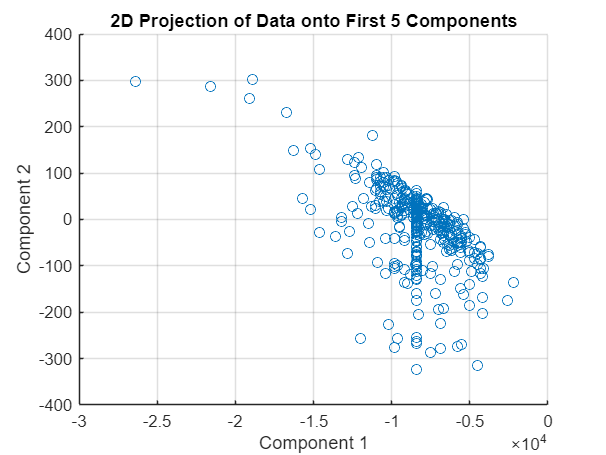


% Visualize the first two components
figure;
scatter(X_reduced(:, 1), X_reduced(:, 2));
title(['2D Projection of Data onto First ', num2str(k), ' Components']);
xlabel('Component 1');
ylabel('Component 2');
grid on;


% Calculate accuracy
accuracy = sum(y_pred == y_test) / length(y_test) * 100;
disp(['Test Accuracy: ', num2str(accuracy), '%']);

Test Accuracy: 63.3333%


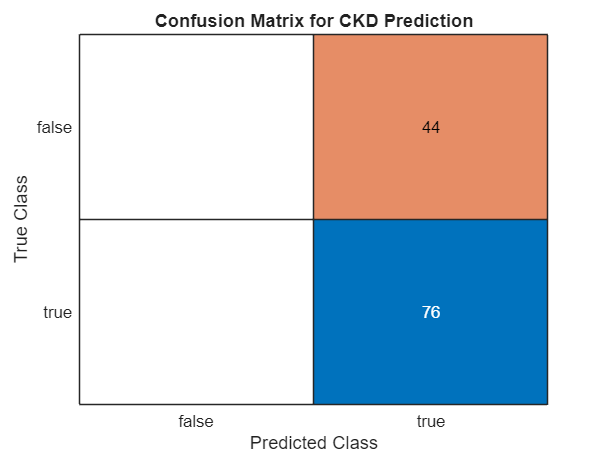


% Display confusion matrix
figure;
confusionchart(y_test, y_pred);
title('Confusion Matrix for CKD Prediction');

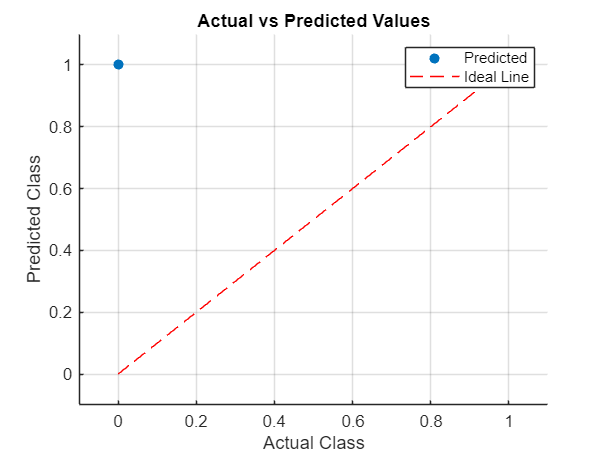


% Actual vs Predicted Plot
figure;
scatter(y_test, y_pred, 'filled');
hold on;
plot([0, 1], [0, 1], 'r--');  % Ideal line (y = x)
title('Actual vs Predicted Values');
xlabel('Actual Class');
ylabel('Predicted Class');
xlim([-0.1, 1.1]);
ylim([-0.1, 1.1]);
grid on;
legend('Predicted', 'Ideal Line');
hold off;

Using SVD not only reduced the dimensionality of the dataset but also minimized noise and redundancy, leading to an optimized input for the logistic regression classifier. This dimensionality reduction allowed the model to achieve high accuracy with fewer computational resources, making it more efficient and potentially more suitable for real-time CKD prediction applications.

Overall, these results underscore the utility of SVD in improving both computational efficiency and predictive accuracy, offering a viable pathway for enhancing early CKD detection.